input = imread('hw2_files/Q3/2/2.png');
compared = imread('hw2_files/Q3/2/original2.jpg')

compared = 570×380×3 uint8 数组
compared(:,:,1) =

   215   215   215   215   215   215   216   216   217   217   217   218   218   218   218   218   220   220   220   221   221   221   221   221   221   221   222   222   222   222   222   222   223   223   223   223   224   224   224   224   225   225   225   225   225   225   225   225   226   226   226   227   227   227   228   228   229   229   229   229   229   229   229   229   229   229   229   229   229   230   230   230   230   231   231   232   232   232   231   231   234   235   235   236   236   236   236   235   236   236   236   237   237   237   237   237   238   238   238   239   239   239   239   239   239   239   239   239   239   239   240   240   241   241   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   240   241   241   240   240   240   241   241   241   241   241   240   240   240   240   240   241   241   241   241   241   241   241   242   242   

[row,col,~] = size(input);
if row > col
    n = row
else
    n = col
end

n = 570

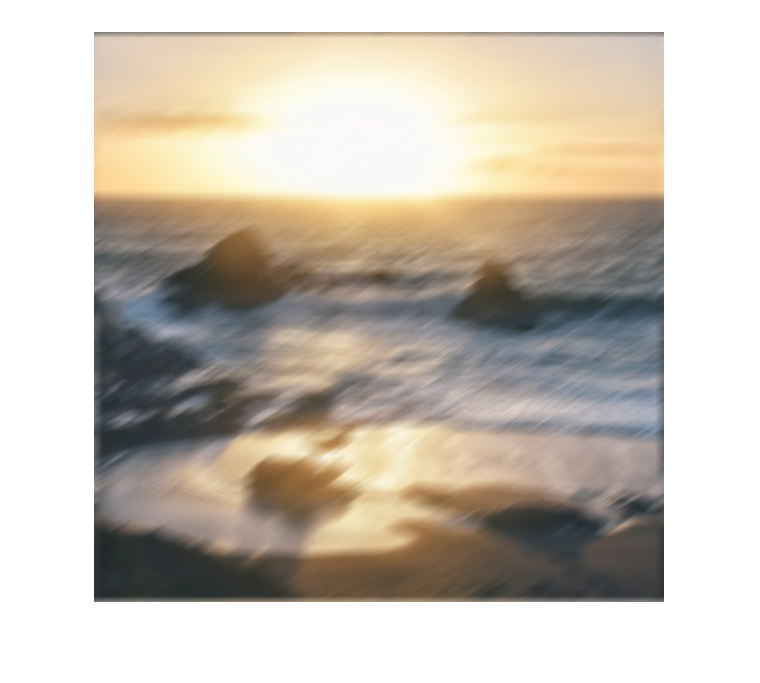

input = imresize(input,[n,n]);

imshow(input)

for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    pic = WeinerFilter(input(:,:,i),h,10);
    input(:,:,i) = pic;
end
input = imresize(input,[row,col])

input = 570×380×3 uint8 数组
input(:,:,1) =

   217   221   224   221   224   224   228   220   221   220   219   221   224   221   223   223   225   221   222   222   224   222   222   225   225   224   226   229   226   225   228   230   228   229   229   231   227   231   230   229   232   232   230   226   224   225   227   227   228   230   230   231   235   232   234   229   230   232   229   231   232   232   235   233   232   232   233   232   233   233   231   232   234   236   236   237   238   238   237   238   241   239   237   239   242   239   240   235   237   241   243   238   238   242   241   238   236   236   236   238   242   240   238   240   240   242   239   238   240   241   241   245   244   241   241   240   240   241   241   238   240   241   242   239   238   238   243   245   243   238   240   240   240   244   245   242   242   242   242   243   240   239   242   240   241   241   245   247   244   243   247   248   249   244   241   242   241   241   244   

rmse = RMSE(input,compared)

rmse = 4.3144

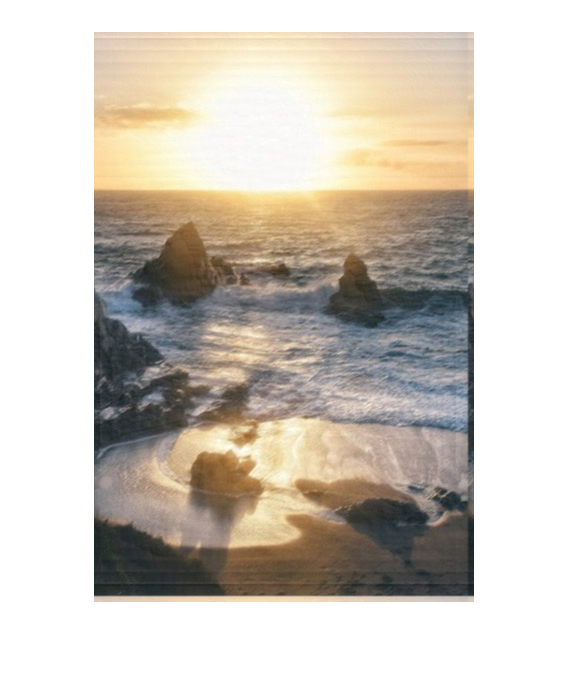

imshow(input);


input = imread('hw2_files/Q3/1/1.png');
[row,col,~] = size(input);
if row > col
    n = row
else
    n = col
end

n = 332

input = imresize(input,[n,n]);
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    testLayer = double(input(:,:,i));
    variant = var(testLayer(:))/1000000
    
    pic = ConstraintLeastSquareFilter(input(:,:,i),h,variant);
    
    input(:,:,i) = pic;
end

variant = 0.0048

variant = 0.0041

variant = 0.0018

input = imresize(input,[row,col])

input = 332×332×3 uint8 数组
input(:,:,1) =

    79    86    80    77    75    78    78    84    81    78    78    80    76    87   104   103   109   104   100   103   110   104   104   111   112   112   111   107   102   103   103   100   101   106   104   104    97    95    98   101   102   100   101   102   105   107   110   109   110   110   109   107   105   101   101   101   103   106   110   109   107   108   111   114   116   117   115   117   116   117   119   118   117   116   116   118   120   120   116   113   113   115   118   120   125   126   127   126   124   125   127   127   124   124   125   127   125   123   123   123   124   123   124   126   127   127   124   123   123   123   124   124   126   128   131   134   138   140   141   142   138   136   137   143   151   157   158   156   154   153   149   144   149   158   163   162   162   159   155   150   151   149   141   135   133   138   146   150   156   158   155   156   157   157   164   167   165   160   156   

rmse = RMSE(input,compared)

二进制数组操作的数组维度必须匹配。

出错 Q3>RMSE (line 180)
    squares = (img-compared).^2;

imshow(input)


input = imread('hw2_files/Q3/1/1.png');
[row,col,~] = size(input);
if row > col
    n = row
else
    n = col
end
input = imresize(input,[n,n]);
for i = 1:3
    [theta,L] = DetectMotionParameters(input(:,:,i));
    h = fspecial('motion',L,theta);
    
    testLayer = double(input(:,:,i));
    variant = var(testLayer(:))/1000000
    pic = CLSFilter(input(:,:,i),h,variant);
    input(:,:,i) = pic;
end
input = imresize(input,[row,col])
rmse = RMSE(input,compared)
imshow(input)


function ret = WeinerFilter(layer, psf, K)
    [psf_row, psf_col] = size(psf);
    [row,col] = size(layer);
    psf_padded = zeros([row,col]);
    psf_padded(1:psf_row, 1:psf_col) = psf;
    psf_padded = psf_padded / sum(psf_padded,"all");
    psf_dft = fft2(psf_padded);
    
    testLayer = double(layer);
    estimated_nsr = K / var(testLayer(:));
    
    img_dft = fft2(layer);
    psf_dft_abs = abs(psf_dft).^2;
    dmp_factor = psf_dft_abs./(psf_dft_abs+estimated_nsr*ones([row,col]));
    layer_psf_fft_ratio = img_dft./psf_dft;
    result = abs(ifft2(dmp_factor.*layer_psf_fft_ratio));
    ret = uint8(result);
end

function ret = ConstraintLeastSquareFilter(layer,psf,gamma)
    layer = double(layer);
    [row,col] = size(layer);
    
    img_dft = fft2(layer);
    
    psf_padded = psf2otf(psf, [row,col]);
    
    laplacian = [0,-1,0;-1,4,-1;0,-1,0];
    laplacian_padded = psf2otf(laplacian,[row,col]);
    
    numerator = conj(psf_padded);
    denominator = psf_padded.^2+gamma*(laplacian_padded.^2);
    
    result = ifft2(numerator.*img_dft./denominator);
    ret = uint8(result);
end

function ret = CLSFilter(layer,psf,gamma)
    layer = double(layer);
    [row,col] = size(layer);
    [psf_row,psf_col] = size(psf);
    
    img_dft = fft2(layer);
    
    psf_padded = zeros([row,col]);
    psf_padded(1:psf_row,1:psf_col) = psf;
    psf_padded = psf_padded/sum(psf_padded,"all");
    
    laplacian = [0,-1,0;-1,4,-1;0,-1,0];
    laplacian_padded = zeros([row,col]);
    laplacian_padded(1:3,1:3) = laplacian;
       
    psf_dft = fft2(psf_padded);
    laplacian_dft = fft2(laplacian_padded);
    laplacian_dft_abs = (abs(laplacian_dft)).^2;
    psf_dft_abs = (abs(psf_dft)).^2;
    
    temp1 = psf_dft_abs ./ (psf_dft_abs + gamma * laplacian_dft_abs);
    temp2 = img_dft ./ psf_dft;
    temp = abs(ifft2(temp1 .* temp2));
    ret = uint8(temp);
end


function [theta,L] = DetectMotionParameters(layer)
    [row,col] = size(layer);
    fshift = fftshift(fft2(layer));
    magintude = 15*log(abs(fshift));
    
    T = 1-imbinarize(uint8(magintude),"adaptive","Sensitivity",0.65);
    kernel = ones([3,3],"uint8");
    morph = imopen(T,kernel);
    kernel = ones([1,9],"uint8");
    morph = imclose(morph,kernel);
    BW1 = edge(morph,'Canny');
    
    [H,T,R] = hough(BW1);
    P  = houghpeaks(H,5,'threshold',ceil(0.3*max(H(:))));
    lines = houghlines(BW1,T,R,P,'FillGap',5,'MinLength',7);
    theta_rotate = lines(1).theta;
    theta = 180-theta_rotate;
    
    rotated = imrotate(uint8(magintude),theta_rotate);
%     imshow(rotated)
    
    proj = sum(rotated,1);
    xaxis = 1: length(proj);
%     figure;
%     plot(xaxis,proj);
    
    [~,maxIndex] = max(proj);
    for i = 1:100
        if proj(maxIndex-i) - proj(maxIndex-i-1) < -1000
            index_1 = i;
            break
        end
    end
    for i = 1:100
        if proj(maxIndex+i) - proj(maxIndex+i+1) < -1000
            index_2 = i;
            break
        end
    end
    
    if abs(index_1 - index_2) >= 5
        index_1 = max([index_1, index_2]);
        index_2 = max([index_1, index_2]);
    end
    
    L = 2 * col / (index_1 + index_2);
end

function ret = RMSE(img,compared)
    [row,col] = size(compared);
    squares = (img-compared).^2;
    sum_squares = sum(squares,"all");
    ret = sqrt(sum_squares/(3*row*col));
end